# Daniel Chang: Lab 1

**Exercise 1**

% help rand

A = rand(3)

A =     0.1439    0.1463    0.6235
    0.5911    0.3804    0.5508
    0.5390    0.3148    0.7683


% zeros matrix for B to hold as place holder values 
B = zeros(3)

B =      0     0     0
     0     0     0
     0     0     0


% running a nested for loop, going through each row, then going through
% eacn entry of that row, setting each entry of B equal to its
% corresponding entry in A after squaring it
for i = 1:3
    for j = 1:3
        B(i,j) = A(i,j)^2;
    end
end
B

B =     0.0207    0.0214    0.3887
    0.3494    0.1447    0.3034
    0.2905    0.0991    0.5903


**Exercise 2**

function N = factorial_recur(n);
    % base case for the factorial function 
    if n == 1 
        N = 1;
    else
    % multiplying current values with its previous value, repeating until
    % base case is hit
        N = n * factorial_recur(n - 1);
    end
end

% 4 * 3 * 2 * 1 = 24
factorial_recur(4)  

ans = 24

% 3 * 2 * 1
factorial_recur(3)   

ans = 6

**Exercise 3**

% Method 1
A = rand(3,3);
% setting timer before for loop
tic
B = zeros(3,3);
for i = 1:3
    for j = 1:3
        B(i,j) = A(i,j)^2;
    end
end
% ending timer after the end of the for loop
t1 = toc;
% printing out the time for the for loop
fprintf("For loop time: %f seconds\n", t1)

For loop time: 0.000846 seconds


% Method 2: element-wise operator
% setting time before doing the element wise operation
tic
B2 = A.^2;
% stopping time after doing the element wise operation
t2 = toc;
% printing out the time for element wise operation
fprintf("Element-wise time: %f seconds\n", t2)

Element-wise time: 0.000526 seconds


**Exercise 4**

% 5x5 matrix with random values
A = rand(5)

A =     0.8499    0.4533    0.8642    0.4422    0.4247
    0.7488    0.8122    0.3048    0.4002    0.5668
    0.6728    0.0746    0.0632    0.1704    0.7033
    0.3859    0.0177    0.7072    0.6013    0.5222
    0.1463    0.9221    0.4393    0.5447    0.2854


% finding all entries in the matrix that are less 1/4 and greater than 1/6
entries = find(A < 1/4 & A > 1/6)

entries = 18

% converting the linear index of entries to a matrix index (row, col)
[row, col] = ind2sub(size(A), entries)

row = 3

col = 4

fprintf("(row, col) pairs of entries between 1/6 and 1/4:\n")

(row, col) pairs of entries between 1/6 and 1/4:


% for loop that runs through the length of rows or cols, should be the same
% for both bc both are dependent on the same number of entries
% printing out row and col index corresponding to each entry as a pair
for k = 1:length(row)
    fprintf("(%d, %d)\n", row(k), col(k))
end

(3, 4)


**Exercise 5**

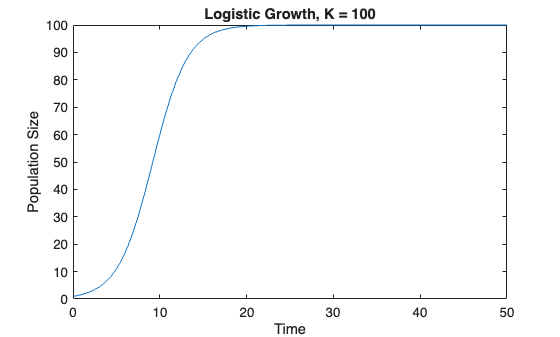

% growth rate
r = 0.5;
% initial time
t0 = 0;
% final time
tf = 50;
% initial population size
N0 = 1;

% plot 1 where K = 100
K = 100; % carrying capacity is K = 100
% numerically solving the ODE using ode45
[T1, N1] = ode45(@(t,N) logGrowth(t,N,r,K), [t0 tf], N0);
% graphing the plot 
% figure opens window   
figure 
plot(T1, N1)
xlabel('Time')
ylabel('Population Size')
title('Logistic Growth, K = 100')

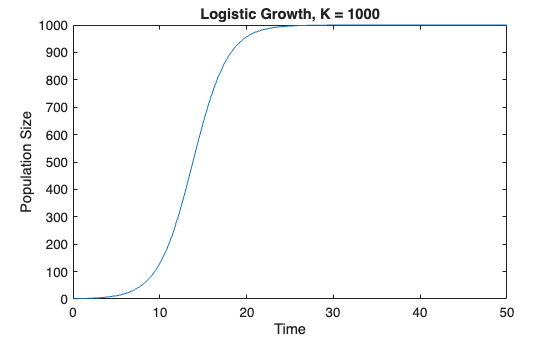

% plot 2 where K = 1000 which 100 x 10 = 1000, so its the same order
K = 1000; % carrying capacity is K = 1000
% numerically solving the ODE using ode45
[T1, N1] = ode45(@(t,N) logGrowth(t,N,r,K), [t0 tf], N0);
% graphing the plot 
% figure opens window   
figure 
plot(T1, N1)
xlabel('Time')
ylabel('Population Size')
title('Logistic Growth, K = 1000')


% defining the function for Log Growth with paremeters r and K as well
% r being the growth rate and K being the carrying capacity
function dNdt = logGrowth(t, N, r, K)
    dNdt = r * N .* (1 - N/K);
end

**Findings for Exercise 5**

Both plots display an S-shaped logistic growth curve where the population grows rapidly before leveling off at its carrying capacity K. A higher K results in a larger final population size, showing that K, the carrying capacity, determines the population's upper limit that the environment can support.

In this case, the first plot which uses a carrying capacity of 100 levels off at 100, and the second plot which uses a carrying capacity of 1000 levels off at 1000. That being said, K in terms of the graphs represents the peaks of where they levels off, and the value of K and the height of peak have a direct relationship. 

**Exercise 6**

% setting y as a symbolic function of t
syms y(t)
% definig cos(20*t) as an ODE
eqn = diff(y,t) == cos(20*t);
% defining the initial conditions given in the question
cond = y(0) == 1;                 
% solving for function of y using dsolve()
ySol = dsolve(eqn, cond);    
ySol

$$ySol = \frac{\sin\left(20\,t\right)}{20}+1$$

t_analysis = 0:0.01:10

t_analysis =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


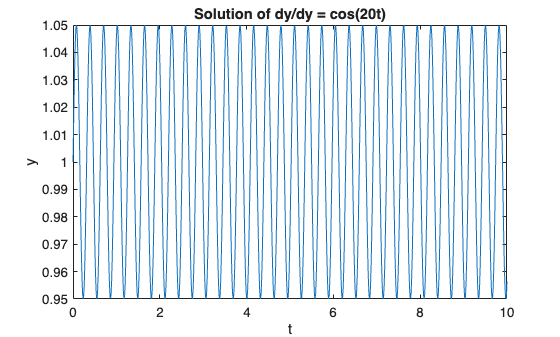

figure
plot(t_analysis, double(subs(ySol, t, t_analysis)))
xlabel('t')
ylabel('y')
title("Solution of dy/dy = cos(20t)")

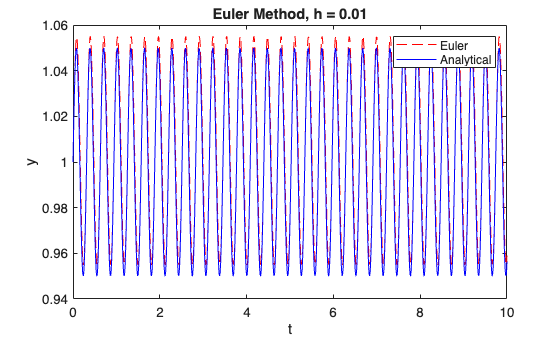

% EULER'S METHOD -----------------------------------------------------------------------------
% h = 0.01

% setting up values
t_start = 0; h = 0.01; t_end = 10; y_start = 1;

% setting up time points with respect to t_start and t_end
t_num = t_start:h:t_end;

% output for eulers using the eul.m provided
output_eul = eul(@cos_ode, t_start, h, t_end, y_start);

% plotting
figure

% plotting euler graph in red, plotting analysis graph in blue
plot(t_num, output_eul, 'r--', t_analysis, double(subs(ySol,t,t_analysis)), 'b-')
xlabel('t'), ylabel('y')
title('Euler Method, h = 0.01')
legend('Euler', 'Analytical')

% checking dimensions of the output of eul
size(output_eul)

ans =         1001           1


% checking dimensions of the output of analytical solution
size(double(subs(ySol,t,t_num)))

ans =            1        1001


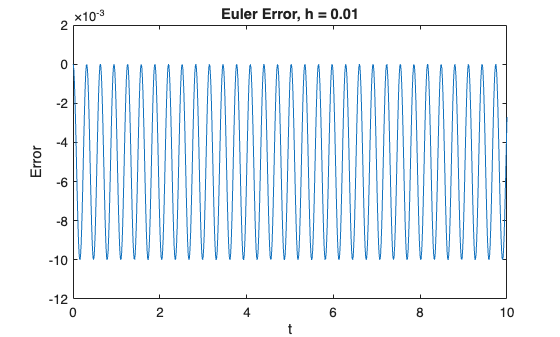

% euler error = analytical - euler
% have to subtract by the transpose so the dimensions match up 
error_eul = double(subs(ySol,t,t_num)) - output_eul'; 

% plotting 
figure

% plotting time points against error_eul
plot(t_num, error_eul)                
xlabel('t'), ylabel('Error')
title('Euler Error, h = 0.01')

% printing the max error over (0,10)
fprintf('Euler max error (h=0.01): %f\n', max(abs(error_eul(:)))) 

Euler max error (h=0.01): 0.010003


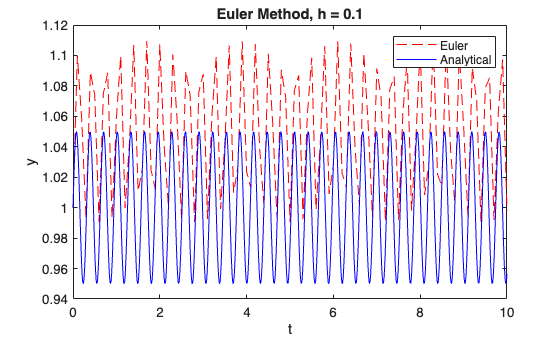

% h = 0.1
% same code as above, only difference is changing h = 0.1
h = 0.1;

% setting up time points with respect to t_start and t_end
t_num = t_start:h:t_end;

% output for eulers using the eul.m provided
output_eul = eul(@cos_ode, t_start, h, t_end, y_start);

% plotting
figure

% plotting euler graph in red, plotting analysis graph in blue
plot(t_num, output_eul, 'r--', t_analysis, double(subs(ySol,t,t_analysis)), 'b-')
xlabel('t'), ylabel('y')
title('Euler Method, h = 0.1')
legend('Euler', 'Analytical')

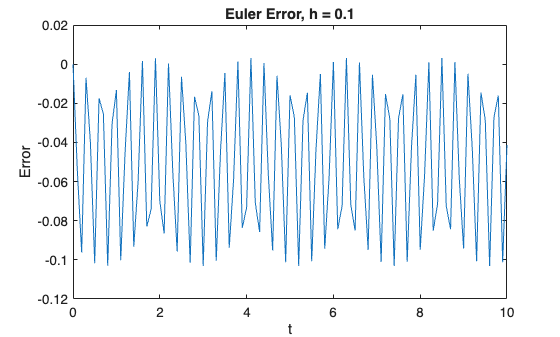

% euler error = analytical - euler
error_eul = double(subs(ySol,t,t_num)) - output_eul'; 

% plotting 
figure

% plotting time points against error_eul
plot(t_num, error_eul)                
xlabel('t'), ylabel('Error')
title('Euler Error, h = 0.1')

% printing the max error over (0,10)
fprintf('Euler max error (h=0.1): %f\n', max(abs(error_eul(:))))

Euler max error (h=0.1): 0.103106


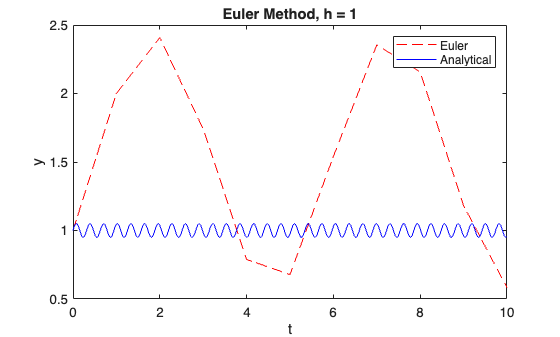

% h = 1
% same code as above, only difference is changing h = 1
h = 1;

% setting up time points with respect to t_start and t_end
t_num = t_start:h:t_end;

% output for eulers using the eul.m provided
output_eul = eul(@cos_ode, t_start, h, t_end, y_start);

% plotting
figure

% plotting euler graph in red, plotting analysis graph in blue
plot(t_num, output_eul, 'r--', t_analysis, double(subs(ySol,t,t_analysis)), 'b-')
xlabel('t'), ylabel('y')
title('Euler Method, h = 1')
legend('Euler', 'Analytical')

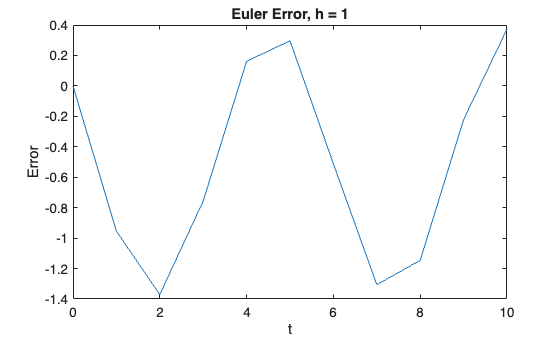

% euler error = analytical - euler
error_eul = double(subs(ySol,t,t_num)) - output_eul'; 

% plotting 
figure

% plotting time points against error_eul
plot(t_num, error_eul)                
xlabel('t'), ylabel('Error')
title('Euler Error, h = 1')

% printing the max error over (0,10)
fprintf('Euler max error (h=1): %f\n', max(abs(error_eul(:))))

Euler max error (h=1): 1.370826


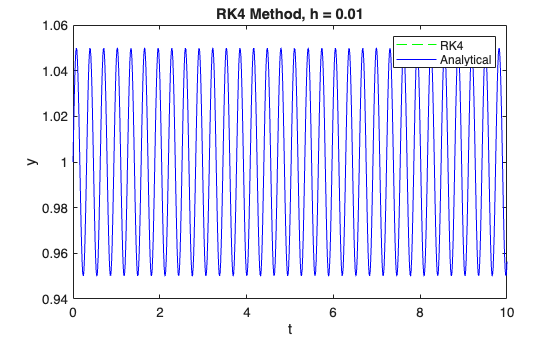

% RK4 Method ------------------------------------------------------------------
% h = 0.01

h = 0.01;

% setting up time points with respect to t_start and t_end
t_num = t_start:h:t_end;

% output for RK4 using the RK4.m provided
output_RK4 = RK4(@cos_ode, t_start, h, t_end, y_start);

% plotting
figure

% plotting RK4 graph in green, plotting analysis graph in blue
plot(t_num, output_RK4, 'g--', t_analysis, double(subs(ySol,t,t_analysis)), 'b-')
xlabel('t'), ylabel('y')
title('RK4 Method, h = 0.01')
legend('RK4', 'Analytical')

% checking dimensions of the output of RK4
size(output_RK4)

ans =         1001           1


% checking dimensions of the output from the analytical solution
size(double(subs(ySol,t,t_num)))

ans =            1        1001


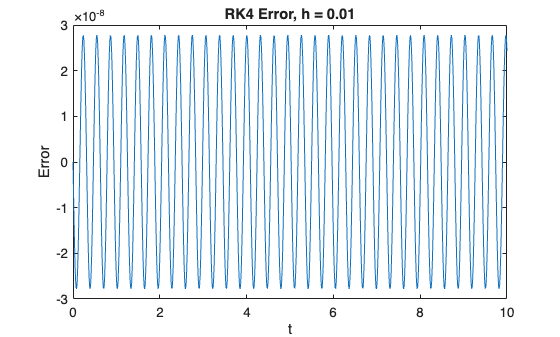

% RK4 error = analytical - RK4
% have to subtract by the transpose so the dimensions match up 
error_RK4 = double(subs(ySol,t,t_num)) - output_RK4'; 

% plotting 
figure

% plotting time points against error_RK4
plot(t_num, error_RK4)                
xlabel('t'), ylabel('Error')
title('RK4 Error, h = 0.01')

error_RK4

error_RK4 = 1.0e-07 *

         0   -0.0553   -0.1083   -0.1570   -0.1995   -0.2340   -0.2592   -0.2741   -0.2780   -0.2708   -0.2529   -0.2248   -0.1879   -0.1434   -0.0932   -0.0392    0.0162    0.0711    0.1231    0.1702    0.2105    0.2424    0.2646    0.2764    0.2770    0.2667    0.2457    0.2149    0.1756    0.1292    0.0777    0.0231   -0.0324   -0.0866   -0.1374   -0.1827   -0.2207   -0.2499   -0.2692   -0.2777   -0.2751   -0.2616   -0.2377   -0.2042   -0.1627   -0.1146   -0.0620   -0.0069    0.0485    0.1019


% printing the max error over (0,10)
fprintf('RK4 max error (h=0.01): %f\n', max(abs(error_RK4(:)))) 

RK4 max error (h=0.01): 0.000000


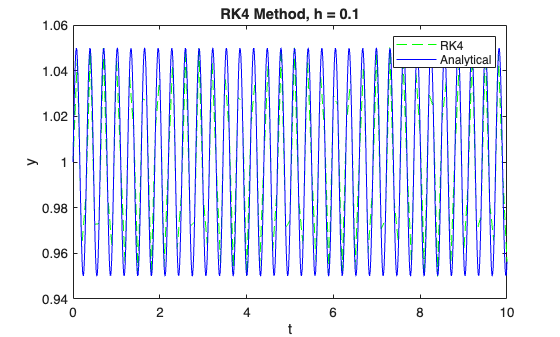

% h = 0.1
% same code as above, only difference is changing h = 0.1
h = 0.1;

% setting up time points with respect to t_start and t_end
t_num = t_start:h:t_end;

% output for RK4 using the RK4.m provided
output_RK4 = RK4(@cos_ode, t_start, h, t_end, y_start);

% plotting
figure

% plotting RK4 graph in green, plotting analysis graph in blue
plot(t_num, output_RK4, 'g--', t_analysis, double(subs(ySol,t,t_analysis)), 'b-')
xlabel('t'), ylabel('y')
title('RK4 Method, h = 0.1')
legend('RK4', 'Analytical')

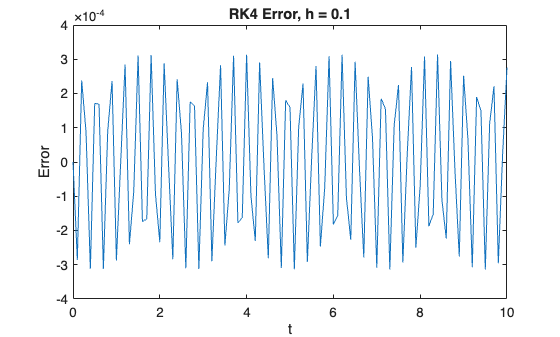

% RK4 error = analytical - RK4
error_RK4 = double(subs(ySol,t,t_num)) - output_RK4'; 

% plotting 
figure

% plotting time points against error_RK4
plot(t_num, error_RK4)                
xlabel('t'), ylabel('Error')
title('RK4 Error, h = 0.1')

% printing the max error over (0,10)
fprintf('RK4 max error (h=0.1): %f\n', max(abs(error_RK4(:))))

RK4 max error (h=0.1): 0.000314


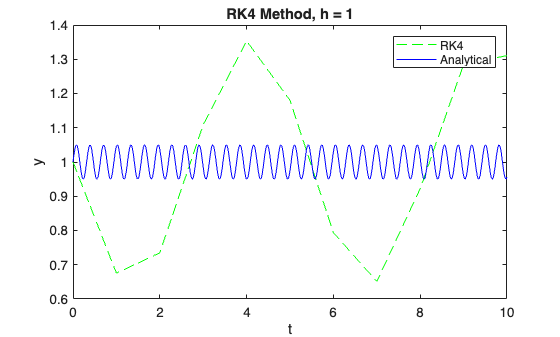

% h = 1
% same code as above, only difference is changing h = 1
h = 1;

% setting up time points with respect to t_start and t_end
t_num = t_start:h:t_end;

% output for RK4 using the Rk4.m provided
output_RK4 = RK4(@cos_ode, t_start, h, t_end, y_start);

% plotting
figure

% plotting Rk4 graph in green, plotting analysis graph in blue
plot(t_num, output_RK4, 'g--', t_analysis, double(subs(ySol,t,t_analysis)), 'b-')
xlabel('t'), ylabel('y')
title('RK4 Method, h = 1')
legend('RK4', 'Analytical')

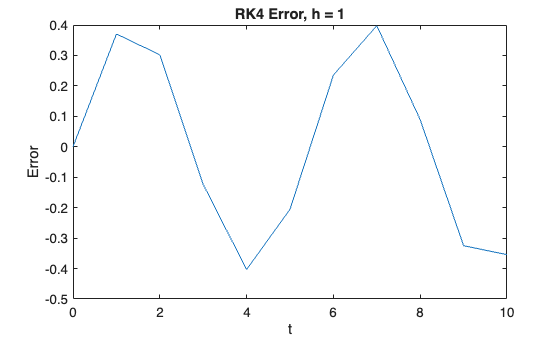

% RK4 error = analytical - RK4
error_RK4 = double(subs(ySol,t,t_num)) - output_RK4'; 

% plotting 
figure

% plotting time points against error_RK4
plot(t_num, error_RK4)                
xlabel('t'), ylabel('Error')
title('RK4 Error, h = 1')

% printing the max error over (0,10)
fprintf('RK4 max error (h=1): %f\n', max(abs(error_RK4(:))))

RK4 max error (h=1): 0.403184


% ode function of cos(20*t)
function dydt = cos_ode(t, y)
    dydt = cos(20*t);              % defines dy/dt = cos(20t)
end

**Euler's Method:** As step size decreases, the error decreases. With h = 0.01 the Euler solution graph is very similar to the analytical solution graph. However, when h = 0.1 or 1, the error grows much larger. This is due to the fact that Euler uses the slope value at that current point. That being said, larger steps cause it to be farther from the true solution. Euler is a first-order method, so its error scales roughly proportional to step size. For example, increasing h from 0.01 to 0.1 (10x) increases the max error from 0.010 to 0.103 (roughly 10x).

**RK4:** RK4 follows the same relationship where smaller step size means smaller error. However when comparing the graphs between Euler and RK4, RK4's errors are much smaller than that of Euler's. At h = 0.1, RK4 closely follows the analytical solution where Euler had already diverged significantly from the true solution. RK4 is a fourth-order method, so its error scales as h^4, meaning it decreases much more rapidly with smaller step sizes.

Both methods improve with smaller step sizes, but RK4 is much more accurate than Euler at every step size. At h = 0.01, Euler's max error is 0.010003 while RK4's max error is essentially 0.000000. At h = 0.1, Euler's max error is 0.103 while RK4's max error is only 0.000314, making RK4 about 300 times more accurate. At h = 1, Euler's max error is 1.370826 while RK4's max error is 0.403184. This is because RK4 uses a weighted average of 4 slopes at each step rather than just one slope from one step, giving a better approximation of the true solution. When h = 1, both methods fail to capture the dynamics because the step size exceeds the oscillation period of cos(20t), which is approximately pi/10 = 0.314 (T = 2pi/w = 2pi/20 = pi/10)